
% Program to get the Gauss-Legendre Quadrature results (Vectorized)
clear;clc;

dbstop if error
format long e
[x]= [-0.99555697 -0.976663921 -0.942974571 -0.894991998 -0.833442629 -0.759259263 -0.673566368...
    -0.57766293 -0.473002731 -0.361172306 -0.243866884 -0.122864693 0 0.122864693 0.243866884 0.361172306...
    0.473002731 0.57766293 0.673566368 0.759259263 0.833442629 0.894991998 0.942974571 0.976663921...
    0.99555697];
[weight]=[0.011393799	0.026354987	0.040939157	0.054904696	0.068038334	0.0801407	0.091028262...
    0.100535949	0.108519624	0.114858259	0.119455764	0.122242443	0.123176054	0.122242443	0.119455764...
    0.114858259	0.108519624	0.100535949	0.091028262	0.0801407	0.068038334	0.054904696	0.040939157...
    0.026354987	0.011393799];
% [x]=xlsread('Gauss-Legendre Quadrature','Sheet1','b1:z1');
% [weight]=xlsread('Gauss-Legendre Quadrature','Sheet1','b2:z2');

E=2e11;               %Young’s modulus
k=6e8;                  %hardening parameter
b=3;                      %weakening scales distribution exponent
nu=0.3;                 %poisson's ratio
tt=2e8;                  %torsion fatigue limit
ff=2.5e8;              %bending fatigue limit
ac=(tt-ff/sqrt(3))/(ff/3); %crossland criterial constant
bc=tt;                    %crossland criterial constant
sigu=8e8;             %ultimite stress
gam=0.5;              %material parameter from Chaboche law(Wohler curve exponent)
y=6.38e8;            %macroscopic yield stress
WF=3e6;             %dissipated energy to failure per unit volume
load=5e8;            %cyclic load
loadtensor= [load 0 0;0 0 0;0 0 0];
stepnumber=200;        %devide one cycle in 200 parts
f=50;                            %frequency of load

%---------------------numerical method-----------------------------
alp=0.5;
D=0;             %initial damage
n=1;       %initial recording point
G = (1 - (1 - D).^(gam + 1)).^(1-alp);
%---------------------to get the the first Sb-----------------------------
stress11=load*sin(2*pi/stepnumber);
m=1/3*sum(stress11+0+0);
dev1=[stress11 0 0 ;0 0 0 ;0 0 0 ]-m*diag([1,1,1]);
dev11=dev1(1,1); dev12=dev1(1,3); dev13=dev1(1,3);
dev21=dev1(2,1); dev22=dev1(2,2); dev23=dev1(2,3);
dev31=dev1(3,1); dev32=dev1(3,2); dev33=dev1(3,3);
s= (x/2+1/2).^(1/(1-b)); %1*25

trial11=dev11; trial12=dev12; trial13=dev13;
trial21=dev21; trial22=dev22; trial23=dev23;
trial31=dev31; trial32=dev32; trial33=dev33;

normtrial(1)=norm([trial11, trial12, trial13; trial21, trial22, trial23;trial31, trial32, trial33],'fro');
eta=bsxfun(@minus,bsxfun(@times,normtrial(1)/y,s),1); %1*25
eta(eta<0)=0;

Sb11=bsxfun(@rdivide,trial11,bsxfun(@plus,eta,1));Sb12=bsxfun(@rdivide,trial12,bsxfun(@plus,eta,1));Sb13=bsxfun(@rdivide,trial13,bsxfun(@plus,eta,1));
Sb21=bsxfun(@rdivide,trial21,bsxfun(@plus,eta,1));Sb22=bsxfun(@rdivide,trial22,bsxfun(@plus,eta,1));Sb23=bsxfun(@rdivide,trial23,bsxfun(@plus,eta,1));
Sb31=bsxfun(@rdivide,trial31,bsxfun(@plus,eta,1));Sb32=bsxfun(@rdivide,trial32,bsxfun(@plus,eta,1));Sb33=bsxfun(@rdivide,trial33,bsxfun(@plus,eta,1));
%1*25 for each Sb element
Sbtensor=[Sb11; Sb12; Sb13; Sb21; Sb22; Sb23;Sb31; Sb32; Sb33];
normSb=sqrt(sum(Sbtensor.^2));
% existsOnGPU(normSb)



tic;
while G<1
    stress11=load*sin((n)*2*pi/stepnumber);
    m=1/3*sum(stress11+0+0);
    dev1=[stress11 0 0 ;0 0 0 ;0 0 0 ]-m*diag([1,1,1]);
    dev11=dev1(1,1); dev12=dev1(1,2); dev13=dev1(1,3);
    dev21=dev1(2,1); dev22=dev1(2,2); dev23=dev1(2,3);
    dev31=dev1(3,1); dev32=dev1(3,2); dev33=dev1(3,3);
    
    stress11=load*sin((n+1)*2*pi/stepnumber);
    m=1/3*sum(stress11+0+0);
    devn=[stress11 0 0;0 0 0;0 0 0]-m*diag([1,1,1]);
    dev11g=devn(1,1); dev12g=devn(1,2); dev13g=devn(1,3);
    dev21g=devn(2,1); dev22g=devn(2,2); dev23g=devn(2,3);
    dev31g=devn(3,1); dev32g=devn(3,2); dev33g=devn(3,3);
    
    trial11=bsxfun(@plus,Sb11,(dev11g-dev11)); trial12=bsxfun(@plus,Sb12,(dev12g-dev12));trial13=bsxfun(@plus,Sb13,(dev13g-dev13));
    trial21=bsxfun(@plus,Sb21,(dev21g-dev21)); trial22=bsxfun(@plus,Sb22,(dev22g-dev22));trial23=bsxfun(@plus,Sb23,(dev23g-dev23));
    trial31=bsxfun(@plus,Sb31,(dev31g-dev31)); trial32=bsxfun(@plus,Sb32,(dev32g-dev32));trial33=bsxfun(@plus,Sb33,(dev33g-dev33));
    trialtensor=[trial11; trial12; trial13; trial21; trial22; trial23;trial31; trial32; trial33];
    normtrial=sqrt(sum(trialtensor.^2));
    eta=bsxfun(@minus,bsxfun(@times,normtrial/y,s),1); %1*25
    eta(eta<0)=0;
    
    Sb11=bsxfun(@rdivide,trial11,bsxfun(@plus,eta,1));Sb12=bsxfun(@rdivide,trial12,bsxfun(@plus,eta,1));Sb13=bsxfun(@rdivide,trial13,bsxfun(@plus,eta,1));
    Sb21=bsxfun(@rdivide,trial21,bsxfun(@plus,eta,1));Sb22=bsxfun(@rdivide,trial22,bsxfun(@plus,eta,1));Sb23=bsxfun(@rdivide,trial23,bsxfun(@plus,eta,1));
    Sb31=bsxfun(@rdivide,trial31,bsxfun(@plus,eta,1));Sb32=bsxfun(@rdivide,trial32,bsxfun(@plus,eta,1));Sb33=bsxfun(@rdivide,trial33,bsxfun(@plus,eta,1));
    %1*25 for each Sb element
    Sbtensor=[Sb11; Sb12; Sb13; Sb21; Sb22; Sb23;Sb31; Sb32; Sb33];
    normSb=sqrt(sum((Sbtensor.^2)));
    
    Ws=(bsxfun(@minus,normtrial,bsxfun(@rdivide, y,[s]))<=0).*...
        (0)+...
        (bsxfun(@minus,normtrial,bsxfun(@rdivide, y,[s]))>0).*...
        ((E-k)*(1+nu)/(2*E*(E+k*nu))*bsxfun(@times,[weight],bsxfun(@rdivide,bsxfun(@times,bsxfun(@minus,normtrial,bsxfun(@rdivide, y,[s])),y),[s])));
    
    W= sum(Ws);
    G = G+W/WF;
    D=1-(1-G.^(1/(1-alp))).^(1/(gam + 1));
    
    hold on;
    yield1=plot (n,y*s(1).^-1, 'LineStyle', 'none','LineWidth', 1, 'Marker', 'o', 'MarkerSize', 10, ...
        'MarkerEdgeColor',  'none', 'MarkerFaceColor' , 'c');
    Trial1=plot (n,sign(trial11(1))*normtrial(1),'LineStyle', 'none','LineWidth', 1,'Marker', '^', 'MarkerSize', 10, ...
        'MarkerEdgeColor','r', 'MarkerFaceColor','r');
    Sb1=plot (n,sign(Sb11(1))*normSb(1),'LineStyle', 'none','LineWidth', 1,'Marker', 'v', 'MarkerSize', 10, ...
        'MarkerEdgeColor','g', 'MarkerFaceColor','g');
    yield8=plot (n,y*s(8).^-1,'LineStyle', 'none','LineWidth', 1,'Marker', 'o', 'MarkerSize', 10, ...
        'MarkerEdgeColor', 'none', 'MarkerFaceColor', 'b');
    Trial8=plot (n,sign(trial11(8))*normtrial(8),'LineStyle', 'none','LineWidth', 1,'Marker', '^', 'MarkerSize', 10, ...
        'MarkerEdgeColor', [1 0.5 0], 'MarkerFaceColor',[1 0.5 0]);
    Sb8=plot (n,sign(Sb11(8))*normSb(8),'LineStyle', 'none','LineWidth', 1,'Marker', 'v', 'MarkerSize', 10, ...
        'MarkerEdgeColor','k', 'MarkerFaceColor','k');
    
    %   DamageN=plot (t,D,'LineStyle', 'none','LineWidth', 1, 'Marker', 'o', 'MarkerSize', 6, ...
    %    'MarkerEdgeColor',  'none', 'MarkerFaceColor' , 'm');
    
    %---------------------Difference between cyclic load calculation and numerical method as function of time-----------------------------
    %  Gcyc = Gcyc+Wcyc/stepnumber/WF
    %  Dcyc=1-(1-Gcyc.^(1/(1-alp))).^(1/(gam + 1));
    %  hold on
    %  Damagecyc=plot (t,D-Dcyc,'LineStyle', 'none','LineWidth', 1, 'Marker', 'o', 'MarkerSize', 6, ...
    %    'MarkerEdgeColor',  'k', 'MarkerFaceColor' , 'k');
    n=n+1;
end;
toc;

Elapsed time is 0.025476 seconds.


% Elapsed time is 12.505803 seconds.

t=n/stepnumber*1/f;
disp(['Time to failure is ' num2str(t) ' s.']);

Time to failure is 0.2036 s.


sp=actxserver('SAPI.SpVoice');
sp.Speak('Fuck that I finished all this shit finally');

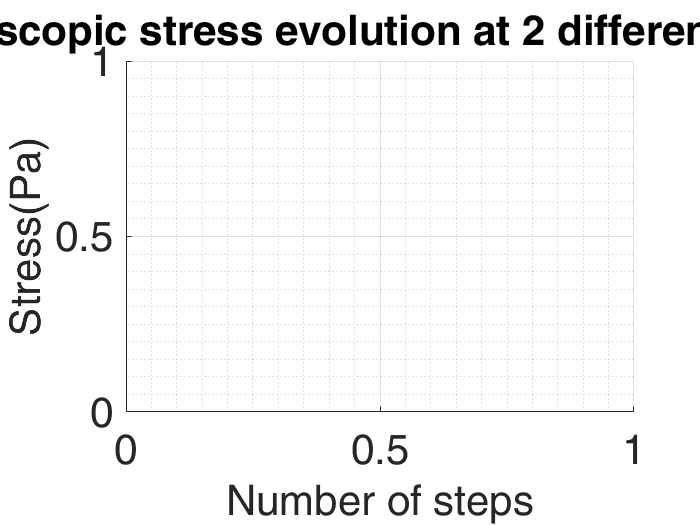

% %---------------------chaboche method-----------------------------
% alp=0.5;
% D=0;             %initial damage
% n=1;       %initial recording point
%   G = (1 - (1 - D).^(gam + 1)).^(1-alp);
%   m=1/3*sum(diag(loadtensor));
%   S1=loadtensor-m*diag([1,1,1]);
%   sqrj1=1/2*sqrt(1/2)*norm(S1,'fro');
%   M=ff^1.233*(1-3*m/sigu);
%   while G<1
%   NF=1/((gam+1)*(1-alp))*(sqrj1/M)^(-gam);
%   G = G+1/stepnumber/NF
%   D=1-(1-G.^(1/(1-alp))).^(1/(gam + 1));
%   t=n/stepnumber*1/f;
%   hold on;
%   DamageC=plot (t,D, 'LineStyle', 'none','LineWidth', 1, 'Marker', 'o', 'MarkerSize', 6, ...
%    'MarkerEdgeColor',  'none', 'MarkerFaceColor' , 'g');
%   n=n+1;
%   end
% %---------------------Cyclic load calculation-----------------------------
% Dcyc=0;
% n=1;
% Gcyc = (1 - (1 - Dcyc).^(gam + 1)).^(1-alp);
% Wcyc=4*(E-k)*(1+nu)*(b-1)/(E*(E+k*nu)*b*(b+1))*norm(loadtensor-(1/3*sum(diag(loadtensor)))*diag([1,1,1]),'fro').^(b+1)*y.^(1-b) ;
% while Gcyc< 1
%  Gcyc = Gcyc+Wcyc/stepnumber/WF
%  Dcyc=1-(1-Gcyc.^(1/(1-alp))).^(1/(gam + 1));
%  t=n/stepnumber*1/f;
%  hold on
%  Damagecyc=plot (t,Dcyc,'LineStyle', 'none','LineWidth', 1, 'Marker', 'o', 'MarkerSize', 6, ...
%    'MarkerEdgeColor',  'none', 'MarkerFaceColor' , 'b');
%  n=n+1;
% end

%---------------------plot settings-----------------------------
grid on;
grid minor;
% axis([0 0.49 -0.04 0.04]);
set(gca ,'FontSize',25);
hXLabel = xlabel('Number of steps' ,'Fontsize' ,25);

hTitle =title('Microscopic stress evolution at 2 different scales ' ,'Fontsize' ,25);
hYLabel =ylabel('Stress(Pa)', 'Fontsize' ,25);

hLegend=legend([yield1,Sb1,Trial1,yield8,Sb8,Trial8],'(\sigma_y-\lambda\Sigma_H)/s_1     at scale s_1','(S-b)               at scale s_1',...
    '(S-b)_{trial}           at scale s_1', '(\sigma_y-\lambda\Sigma_H)/s_8     at scale s_{8}','(S-b)               at scale s_{8}','(S-b)_{trial}           at scale s_{8}');

Undefined function or variable 'yield1'.




% hTitle = title('Damage evolution comparison of three methods' ,'Fontsize' ,30);
% hYLabel = ylabel('Damage', 'Fontsize' ,30);
%  hLegend=legend([DamageN,DamageC,Damagecyc],'Numerical method','Chaboche method',...
%    'Cyclic load calculation');

% hTitle = title('Difference between cyclic load calculation and numerical method as function of time(time step=1/15000)' ,'Fontsize' ,30);

% Adjust font
set(gca, 'FontName', 'Helvetica')
set([hTitle, hXLabel, hYLabel], 'FontName', 'AvantGarde')

set([hXLabel, hYLabel], 'FontSize', 25)
set(hTitle, 'FontSize', 25, 'FontWeight' , 'bold')
set([hLegend, gca], 'FontSize', 25)
% Adjust axes properties
set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'YGrid', 'on', ...
    'XColor', [.3 .3 .3], 'YColor', [.3 .3 .3], ...
    'LineWidth', 1)

set(gcf,'color','w'); %set figure background transparent
set(gca,'color','w'); %set axis transparent
% Maximize print figure
set(gcf,'outerposition',get(0,'screensize'));
set(gcf, 'PaperPositionMode', 'manual');
set(gcf, 'PaperUnits', 'points'); %[ {inches} | centimeters | normalized | points ]
set(gcf, 'PaperPosition', [0 0 1920 1080]); %set(gcf,'PaperPosition',[left,bottom,width,height])
saveas(gcf,'trialsin.png');
% mail2me('job finished',['Elapsed time is ' num2str(toc) ' seconds.']);